# Night 7: Eigenfaces

load classdata_train.mat

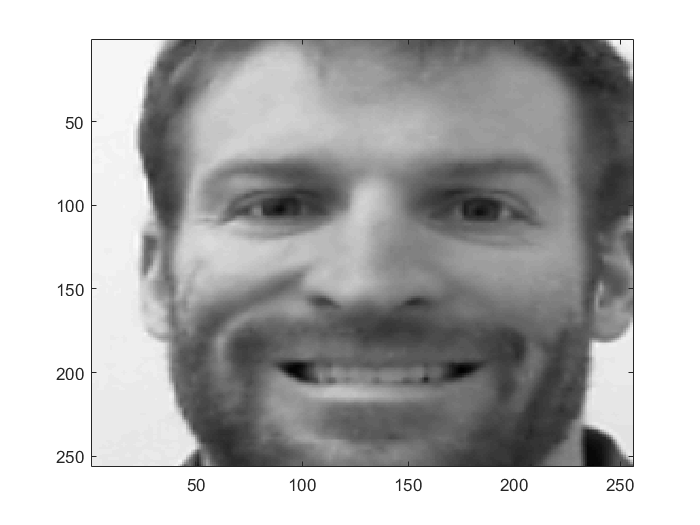

% Make sure images imported successfuly 
imagesc(grayfaces(:,:,44)); colormap('gray')

grayfaces_train = grayfaces

grayfaces_train = grayfaces_train(:,:,1) =

   172   172   172   172   172   172   171   171   171   171   171   172   172   173   173   172   171   170   169   169   169   169   168   168   167   166   165   165   165   165   165   162   159   155   151   148   145   143   142   142   142   143   143   144   147   152   157   157   159   157   154   151   147   142   134   128   119   110   101    92    88    90    92    96    99   102   105   108   111   114   116   118   120   123   125   126   128   130   131   133   134   135   137   138   139   141   143   145   145   146   146   147   146   145   144   143   142   141   140   138   136   135   134   134   133   132   133   134   133   133   133   133   133   131   130   128   127   127   125   125   124   124   123   122   121   119   118   118   117   115   115   113   111   110   109   108   107   105   103   102   102   102   101   100   100    99    98    97    96    94    93    91    89    87    86    84    82    80    77  

% Make matrix A, which contains all image vectors
% Each column of A is an image vector
% You can use downsample if program takes to long
A1 = reshape(grayfaces, 65536, 106);
size(A1)

ans =        65536         106


clear grayfaces

% Normalizing the matrix
A = A1 - repmat((sum(A1,2)./106),1,106);
clear A1

% Find Eigenvectors of covariance matrix
[U,S,V] = svd(transpose(A)*A)

U =    -0.0342   -0.1443   -0.0546   -0.0454    0.0383   -0.1156    0.1227   -0.1013   -0.0193    0.0275   -0.0244    0.0522   -0.0682    0.1345   -0.0515    0.1346   -0.0255    0.0589   -0.0539   -0.2252    0.0387    0.0454   -0.0426   -0.0124    0.0719    0.0925    0.0428   -0.0822    0.0612   -0.0100    0.0443   -0.1413    0.0082   -0.0289    0.0065   -0.0175    0.0546   -0.0614    0.0507    0.0305   -0.0374    0.0218    0.0376   -0.0576   -0.1089    0.0624    0.0921   -0.1271   -0.1616    0.0392
   -0.0221   -0.1331   -0.0170   -0.0608    0.0146   -0.1381    0.0847   -0.1070    0.0152   -0.0766    0.0680   -0.0014   -0.0943    0.0787   -0.0696    0.0364   -0.0439    0.1041    0.0041   -0.1884    0.0639    0.0177   -0.0447   -0.0016    0.0599    0.0609    0.0350   -0.0459    0.0436    0.0039    0.0136   -0.1125   -0.0016   -0.0683   -0.0120   -0.0044    0.0246   -0.1226    0.0363    0.0512    0.0030    0.0541    0.0856   -0.0472   -0.1255    0.0294    0.1624   -0.1446   -0.1045   -0

S = 	1.0e+09 *

    3.5526         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3940         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

V =    -0.0342   -0.1443   -0.0546   -0.0454    0.0383   -0.1156    0.1227   -0.1013   -0.0193    0.0275   -0.0244    0.0522   -0.0682    0.1345   -0.0515    0.1346   -0.0255    0.0589   -0.0539   -0.2252    0.0387    0.0454   -0.0426   -0.0124    0.0719    0.0925    0.0428   -0.0822    0.0612   -0.0100    0.0443   -0.1413    0.0082   -0.0289    0.0065   -0.0175    0.0546   -0.0614    0.0507    0.0305   -0.0374    0.0218    0.0376   -0.0576   -0.1089    0.0624    0.0921   -0.1271   -0.1616    0.0392
   -0.0221   -0.1331   -0.0170   -0.0608    0.0146   -0.1381    0.0847   -0.1070    0.0152   -0.0766    0.0680   -0.0014   -0.0943    0.0787   -0.0696    0.0364   -0.0439    0.1041    0.0041   -0.1884    0.0639    0.0177   -0.0447   -0.0016    0.0599    0.0609    0.0350   -0.0459    0.0436    0.0039    0.0136   -0.1125   -0.0016   -0.0683   -0.0120   -0.0044    0.0246   -0.1226    0.0363    0.0512    0.0030    0.0541    0.0856   -0.0472   -0.1255    0.0294    0.1624   -0.1446   -0.1045   -0

% U is a matrix of the eigenvalues
% s is variance in direction of egienvector s^2 are eigenvalues
% v makes decomposition work (probalby don't have to do anything with it)

% find u 
U1 = (A*V)

U1 =  -168.4089 -195.6021  -13.0740  -13.1830  139.6674  -23.9029   52.0303   39.8601   50.6849  -16.7001   10.4099 -121.5619  129.4018   23.1874   10.9662   38.2275  -70.3679  -41.1379   66.8890   54.7469   12.8015   14.6699  -45.7840  139.8408  -57.0059  -32.5578   -6.9535   -9.3949   38.2144  -39.4418  -16.5869  -24.0173   43.6861  -10.7583    7.1762  -27.9373   11.5025  -67.9310   78.7298  -53.3191   45.7071  -19.4433   41.0712   -1.2775  -24.8132  -18.6312  -40.9983  -17.2117   27.4889   12.7971
 -168.8164 -197.5561  -10.6654  -13.6503  142.8085  -25.3412   52.0413   39.5559   51.2345  -15.5229   10.8612 -121.2394  128.4158   24.5788    9.8933   36.8826  -70.4899  -40.7348   65.8172   53.5210   12.5421   17.8057  -46.6217  141.7085  -56.7525  -32.8960   -7.8890  -11.5907   39.6127  -41.0853  -16.7587  -21.8670   43.2812  -11.2105    6.0387  -26.8503   10.5164  -65.3055   76.0684  -52.7151   46.3808  -18.4281   41.1101   -1.4342  -24.1179  -18.6861  -40.0004  -17.2954   28.5475   1

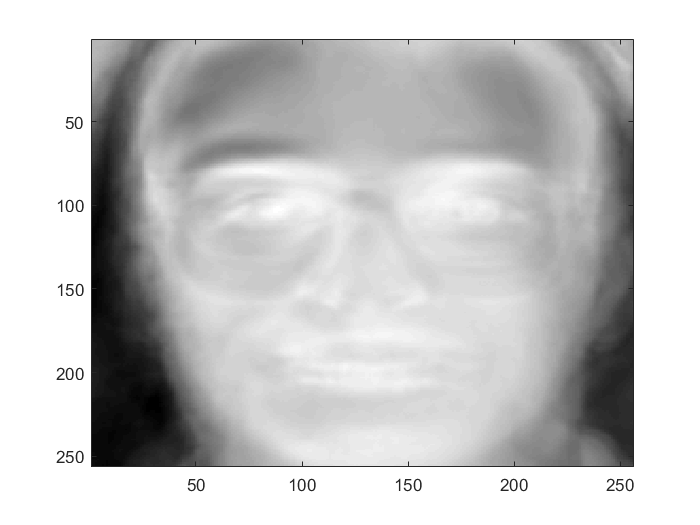

% Determine which eigenvectors are most important (which have the largest eigenvalues)
% and throw out all the unnecessary eigenvectors and values
% try first 10, 20, or 50 vectors
U20 = U1(:,1:20); % extract first 20 entries
V20 = V(:,1:20);
imagesc(reshape(U20(:,1), 256, 256)); colormap('gray')

% Then find out how much of each eigenvector is used to represent each face 
% (find weights)
Wtrain = transpose(U20)*A

Wtrain = 	1.0e+08 *

   -1.2151   -0.7859   -2.3057   -1.8902   -3.8289   -5.1953    4.7078    4.7547   -2.9275   -2.6131    4.2187    4.4387    1.6910    1.9809    1.4811    1.5923   -0.2208    0.1978   -0.2323   -0.2344   -4.8571   -4.1304   -0.5077    0.3257    7.0390    7.0432   -2.1073   -1.9261   -4.1060   -3.4405   -1.6405   -0.4609   -3.5647   -3.8327    1.6195    2.5222   -0.3609   -0.3481    1.6838    1.3816    7.0904    7.0240   -9.7332   -9.7028    3.0682    3.8384    0.1453    1.4645    5.3771    4.8589
   -2.0115   -1.8548    0.3352    0.3396   -0.4185   -0.5966   -1.0731   -1.0129   -0.7566   -0.5579   -0.9118   -0.9185    3.5624    3.3868    0.8130    0.7216    1.2883    1.5792    1.0900    1.0989    0.6137    0.4562    1.1954    0.8207   -0.1927   -0.1578    0.3958    0.4314   -0.6884   -0.4356    0.8333    1.1795   -0.2767   -0.4197   -2.7405   -2.3475    0.1328    0.1515   -2.5207   -2.5259   -0.3918   -0.3301   -1.7068   -1.7612    1.4784    0.6458    1.1712    1.14

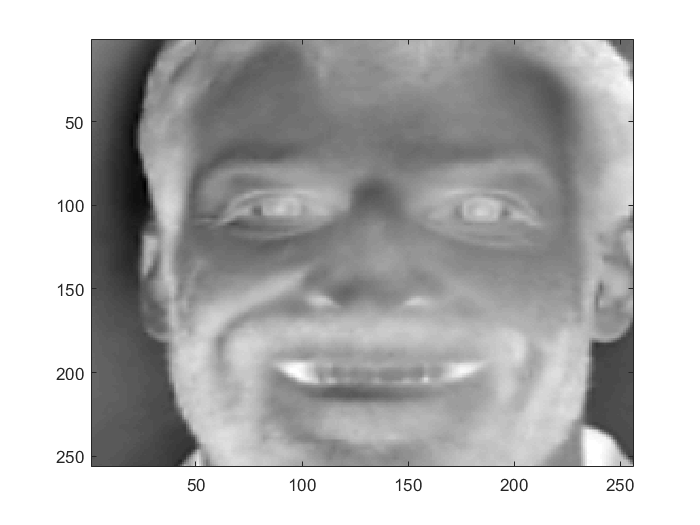

% step 7: get nightmares
I = reshape((Wtrain(:,1))*transpose(A(:,44)),20,256,256);
I1 = squeeze(I(1,:,:));
imagesc(I1); colormap('gray')

% When given a new face, find the weights and compare those to all existing weights 
load classdata_test.mat
% Loads grayfaces and y again
grayfaces_test = grayfaces

grayfaces_test = grayfaces_test(:,:,1) =

   175   175   174   174   173   171   172   172   172   171   171   170   170   171   172   172   172   172   172   172   170   168   168   168   168   168   168   166   164   163   162   160   158   155   152   148   144   139   136   134   134   133   133   137   141   146   151   152   150   148   145   142   139   137   136   134   131   125   120   112   105    99    94    92    92    94    98   101   105   108   111   114   117   119   122   123   125   127   129   130   131   132   134   136   138   140   141   142   143   144   144   146   148   148   148   149   150   151   150   150   148   146   145   143   141   140   140   139   138   138   138   138   137   137   137   138   137   137   136   135   134   134   133   132   131   130   130   129   128   126   125   124   123   121   120   119   119   118   117   116   115   114   113   112   112   111   110   109   109   109   108   107   107   105   104   102   101   100    98    

% Find weights for an image
A1 = reshape(grayfaces, 65536, 318);
size(A1)

ans =        65536         318


Atest = A1 - repmat((sum(A1,2)./424),1,318);
clear A1
Wtest = transpose(U20)*Atest

Wtest = 	1.0e+09 *

   -0.4226   -0.4004   -0.4238   -0.3270   -0.3247   -0.3330   -0.5077   -0.5089   -0.4991   -0.4960   -0.5584   -0.5564   -0.6769   -0.8175   -0.8292   -0.9166   -0.7993   -0.7331    0.1796    0.1841    0.2033    0.2053    0.1950    0.2107   -0.5264   -0.5224   -0.4865   -0.4230   -0.5270   -0.5290    0.1486    0.1511    0.1497    0.1560    0.1588    0.1648   -0.1049   -0.0927   -0.0819   -0.0920   -0.0873   -0.0999   -0.1019   -0.1226   -0.1100   -0.1130   -0.1086   -0.1068   -0.2970   -0.3440
   -0.2383   -0.2371   -0.2434   -0.2324   -0.2299   -0.2315   -0.0192   -0.0216   -0.0193   -0.0244   -0.0313   -0.0326   -0.1033   -0.0934   -0.0928   -0.1017   -0.1052   -0.0895   -0.1458   -0.1348   -0.1525   -0.1469   -0.1690   -0.1703   -0.1101   -0.1293   -0.1279   -0.0894   -0.1254   -0.1211   -0.1541   -0.1488   -0.1569   -0.1544   -0.1533   -0.1420    0.2907    0.2791    0.2846    0.2922    0.2932    0.2824    0.0288    0.0205    0.0308    0.0277    0.0370    0.043

% Select random image from testing set
n = randi([1 318],1,1)

n = 245

Wn = Wtest(:,n);

% for loop to compare every weight vector in train matrix with the selected test vector
WL = zeros(1,106)

WL =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:106
   WL(i) = WL(i)+ sum(abs(Wtrain(:,i)-Wn));
end

[M,I] = min(WL)

M = 2.5070e+08

I = 11

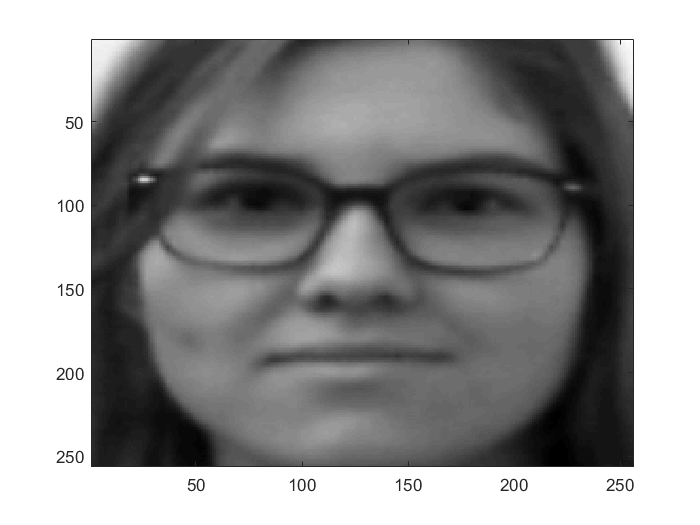

imagesc(grayfaces_train(:,:,I)); colormap('gray')

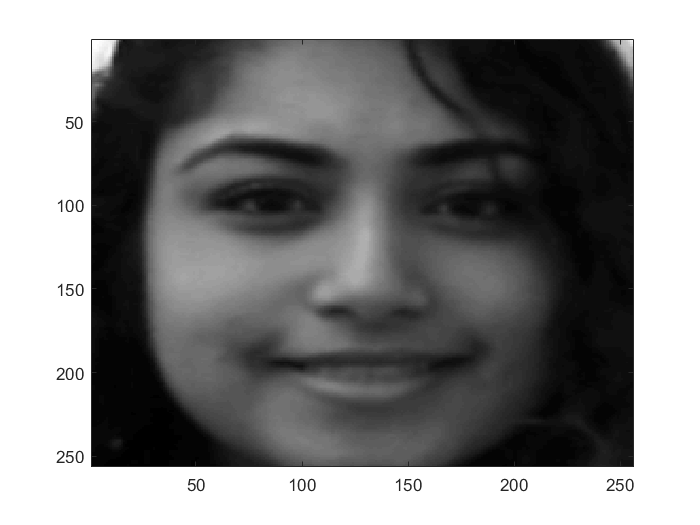

imagesc(grayfaces_test(:,:,n)); colormap('gray')

% load classdata_full.mat